# Test New Pipeline

starting = tic;

%input_path = 'Data/STARmap_data/1000genes/BY1/large/';
%input_path = 'Data/STARmap_data/1000genes/BY3/raw/output/xin/';
input_path = 'Data/STARmap_data/1000genes/BY3/raw/';
dims = [400 400 36 4 6];
useGPU = false;

new_run = new_STARMapDataset(input_path, dims, 'useGPU', useGPU);

Pipeline Obj is generated...


new_run = new_run.LoadCellImages;

====Load Cell Segmentation Images====


new_run = new_run.LoadRawImages;

====Loading raw images====
Loading round 1...
Loading round 2...
Loading round 3...
Loading round 4...
Loading round 5...
Loading round 6...
Collapsed to size 400 by 400 by 36
Collapsing round 1
Collapsing round 2
Collapsing round 3
Collapsing round 4
Collapsing round 5
Collapsing round 6


new_run = new_run.SwapChannels;

====Swap Channels====
Channel 2 <==> Channel 3


%new_run.registeredImages = new_run.rawImages;

new_run = new_run.MinMaxNormalize;

====Min-Max intensity normalization====
Normalizing Round 1...[time = 0.19 s]
Normalizing Round 2...[time = 0.09 s]
Normalizing Round 3...[time = 0.09 s]
Normalizing Round 4...[time = 0.08 s]
Normalizing Round 5...[time = 0.08 s]
Normalizing Round 6...[time = 0.09 s]


new_run = new_run.MorphoRecon;

====Morphological Reconstruction====
Processing Round 1...[time = 12.77 s]
Processing Round 2...[time = 13.61 s]
Processing Round 3...[time = 13.84 s]
Processing Round 4...[time = 13.67 s]
Processing Round 5...[time = 13.80 s]
Processing Round 6...[time = 13.61 s]


new_run = new_run.GlobalRegistration;

====Global Registration====
Method: will
Use overlay: 0
Registering Round [2 / 5] [time=0.030795]
Shifting by 6 -2  1
Registering Round [3 / 5] [time=0.700874]
Shifting by -1  2  0
Registering Round [4 / 5] [time=1.267497]
Shifting by 6 -3  0
Registering Round [5 / 5] [time=1.740790]
Shifting by 0 -2  1
Registering Round [6 / 5] [time=2.223570]
Shifting by 9 -6  1
Applying registration to round [2 / 6], channel 1 [time=2.687605]
Applying registration to round [2 / 6], channel 2 [time=3.105415]
Applying registration to round [2 / 6], channel 3 [time=3.347616]
Applying registration to round [2 / 6], channel 4 [time=3.585060]
Applying registration to round [3 / 6], channel 1 [time=3.830517]
Applying registration to round [3 / 6], channel 2 [time=4.082684]
Applying registration to round [3 / 6], channel 3 [time=4.327974]
Applying registration to round [3 / 6], channel 4 [time=4.567727]
Applying registration to round [4 / 6], channel 1 [time=4.818806]
Applying registration to round [4 / 6],

new_run = new_run.LocalRegistration;

====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 60.91 s]
Round 3 vs. Round 1...[time = 59.02 s]
Round 4 vs. Round 1...[time = 59.02 s]
Round 5 vs. Round 1...[time = 58.49 s]
Round 6 vs. Round 1...[time = 58.56 s]


%new_run = new_run.LoadRegisteredImages(input_path);

new_run = new_run.SpotFinding('Method', "max3d", 'qualityThreshold', 0.7, 'volumeThreshold', 10);

====Spot Finding====
Method: max3d
Number of spots found by max3d: 3920
[time = 2.30 s]


====Reads Extraction====
Geting color sequence for each voxel...
Completed [=================== ]  99% 00:00:00
Geting max color...
Completed [=================   ]  89% 00:00:00
Decoding...



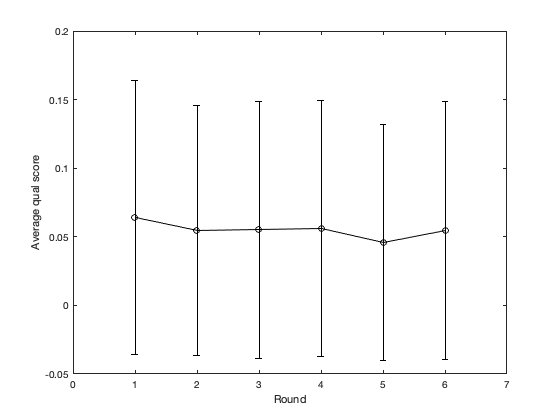

new_run = new_run.ReadsExtraction; 

new_run = new_run.LoadCodebook;

====Load Codebook====
doReverse: 1


====Reads Filtration====
Base in both ends: C --- C
Filtration Statistics:
0.495208 [1395 / 2817] percent of good reads are CNNNNNC


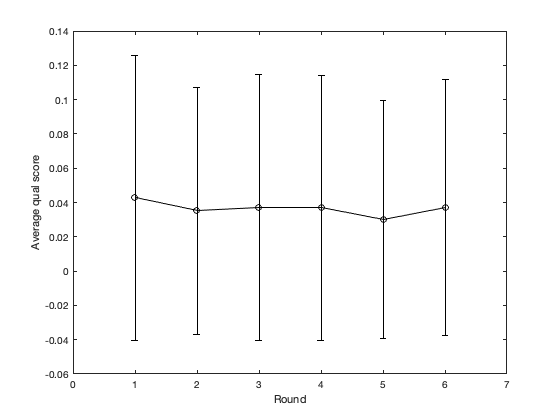

0.494853 [1394 / 2817] percent of good reads are in codebook
0.999283 [1394 / 1395] percent of CNNNNNC reads are in codebook


new_run = new_run.ReadsFiltration;

%

new_run = new_run.SaveReads;
new_run = new_run.AssignReads;
new_run.jobFinished

toc(starting)